# **RS-HL-11: Multi User Simulation**

**UT Austin Oden Institute**

**Hongseok Kim**

**07/12/2024**

## I. Scope

  In this report, the multi user simulation of satellite network control system is presented.

## II. Algorithm 

## III. Code

### III.1 Load the SAT-to-SAT dataset

clear;clc;
% Load the Satellite Contat Dataset
addpath('~/Desktop/Redstone_Project/RS_HL/RS_HL_10_TV_MDP_Functions')
load('/workspace/RS_Dataset/RS_HL_3_dataset.mat')

### III.2 Run MDP

% Parameter Setting
time_index_vector = 100:120;
destination_state = 38;

% Run MDP
MDP = runMDP(sat_to_sat_contact_3d_matrix, time_index_vector,destination_state);

simulation set up complete! 
Policy: 1 -> Value Iteration: 485
Policy: 2 -> Value Iteration: 15
Policy: 3 -> Value Iteration: 5
Policy: 4 -> Value Iteration: 5
Policy: 5 -> Value Iteration: 8
Policy: 6 -> Value Iteration: 10
Policy: 7 -> Value Iteration: 9
Policy: 8 -> Value Iteration: 1
Policy: 9 -> Value Iteration: 1
Policy: 10 -> Value Iteration: 1
Policy: 11 -> Value Iteration: 1


### III.3 User 1 Simulation

start_time = 100;
start_state = 3;

% Run Simulation
[time_list, reward_list, state_list, state_value_list]= simulation_test(start_time,start_state,MDP,time_index_vector,destination_state);

simulation_result_1 = [time_list, state_list, reward_list, state_value_list]

simulation_result_1 =   100.0000    3.0000         0    2.0000
  101.0000    4.0000   -1.0000   10.5000
  102.0000    5.0000   -2.0000   19.0000
  103.0000   31.0000  -17.0000   41.5000
  104.0000   32.0000  -18.0000   50.0000
  105.0000   33.0000  -19.0000   58.5000
  106.0000   34.0000  -20.0000   67.0000
  107.0000   35.0000  -21.0000   75.5000
  108.0000   36.0000  -22.0000   84.0000
  109.0000   37.0000  -23.0000   92.5000


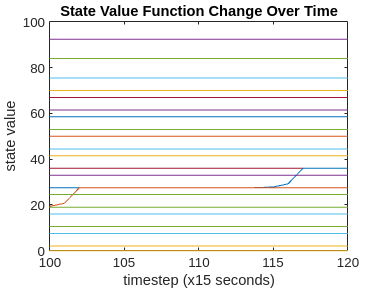

number_of_states = length(sat_to_sat_contact_3d_matrix(1,:,1));
state_value_over_time = zeros(length(time_index_vector),number_of_states);

for t = 1:length(time_index_vector)
    for state_index = 1:number_of_states
        state_value_over_time(t,state_index) = MDP.(['time' num2str(time_index_vector(t))]).(['state' num2str(state_index)]).('state_value');            
    end
end

for state_index = 1:number_of_states
    plot(time_index_vector,state_value_over_time(:,state_index))
    hold on
end

hold off
title('State Value Function Change Over Time')
xlabel('timestep (x15 seconds)')
ylabel('state value')

### III.4 Modification of sat-to-sat contact matrix from simulation 1

sat_to_sat_2 = sat_to_sat_contact_3d_matrix;

for index = 1:length(time_list)-1

    time_index = time_list(index);
    state_index = state_list(index);

    sat_to_sat_2(state_index,:,time_index) = 0;
    sat_to_sat_2(:,state_index,time_index) = 0;
    sat_to_sat_2(state_index,state_index,time_index) = 1;

end

time_index_vector = 100:120;
destination_state = 38;

% Run MDP
MDP = runMDP(sat_to_sat_2, time_index_vector,destination_state);

simulation set up complete! 
Policy: 1 -> Value Iteration: 485
Policy: 2 -> Value Iteration: 15
Policy: 3 -> Value Iteration: 5
Policy: 4 -> Value Iteration: 5
Policy: 5 -> Value Iteration: 8
Policy: 6 -> Value Iteration: 10
Policy: 7 -> Value Iteration: 9
Policy: 8 -> Value Iteration: 1
Policy: 9 -> Value Iteration: 1
Policy: 10 -> Value Iteration: 1
Policy: 11 -> Value Iteration: 1


### III.5 State Value changing over time

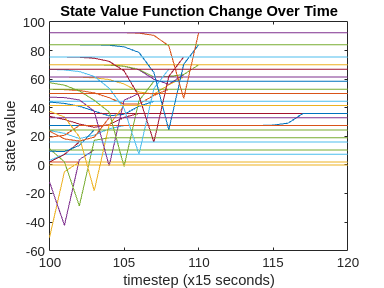

number_of_states = length(sat_to_sat_2(1,:,1));
state_value_over_time = zeros(length(time_index_vector),number_of_states);

for t = 1:length(time_index_vector)
    for state_index = 1:number_of_states
        state_value_over_time(t,state_index) = MDP.(['time' num2str(time_index_vector(t))]).(['state' num2str(state_index)]).('state_value');            
    end
end

for state_index = 1:number_of_states
    plot(time_index_vector,state_value_over_time(:,state_index))
    hold on
end

hold off
title('State Value Function Change Over Time')
xlabel('timestep (x15 seconds)')
ylabel('state value')

### III.6 User 2 Simulation

start_time = 101;
start_state = 3;

% Run Simulation
[time_list, reward_list, state_list, state_value_list] = simulation_test(start_time,start_state,MDP,time_index_vector,destination_state);

simulation_result_2 = [time_list, state_list, reward_list, state_value_list]

simulation_result_2 =   101.0000    3.0000         0   -4.8000
  102.0000    2.0000   -1.0000    2.0000
  103.0000    1.0000   -2.0000   10.5000
  104.0000   46.0000  -17.0000   33.0000
  105.0000   45.0000  -18.0000   41.5000
  106.0000   44.0000  -19.0000   50.0000
  107.0000   43.0000  -20.0000   58.5000
  108.0000   42.0000  -21.0000   67.0000
  109.0000   41.0000  -22.0000   75.5000
  110.0000   40.0000  -23.0000   84.0000


### III.4 Modification of sat-to-sat contact matrix from simulation 2

sat_to_sat_3 = sat_to_sat_2;

for index = 1:length(time_list)-1

    time_index = time_list(index);
    state_index = state_list(index);

    sat_to_sat_3(state_index,:,time_index) = 0;
    sat_to_sat_3(:,state_index,time_index) = 0;
    sat_to_sat_3(state_index,state_index,time_index) = 1;

end

time_index_vector = 100:120;
destination_state = 25;

% Run MDP
MDP = runMDP(sat_to_sat_3, time_index_vector,destination_state);

simulation set up complete! 
Policy: 1 -> Value Iteration: 443
Policy: 2 -> Value Iteration: 13
Policy: 3 -> Value Iteration: 5
Policy: 4 -> Value Iteration: 12
Policy: 5 -> Value Iteration: 5
Policy: 6 -> Value Iteration: 7
Policy: 7 -> Value Iteration: 4
Policy: 8 -> Value Iteration: 1
Policy: 9 -> Value Iteration: 1


### III.5 State Value changing over time

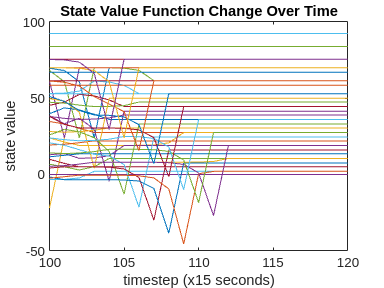

number_of_states = length(sat_to_sat_3(1,:,1));
state_value_over_time = zeros(length(time_index_vector),number_of_states);

for t = 1:length(time_index_vector)
    for state_index = 1:number_of_states
        state_value_over_time(t,state_index) = MDP.(['time' num2str(time_index_vector(t))]).(['state' num2str(state_index)]).('state_value');            
    end
end

for state_index = 1:number_of_states
    plot(time_index_vector,state_value_over_time(:,state_index))
    hold on
end

hold off
title('State Value Function Change Over Time')
xlabel('timestep (x15 seconds)')
ylabel('state value')

### III.6 User 2 Simulation

start_time = 102;
start_state = 9;

% Run Simulation
[time_list, reward_list, state_list, state_value_list] = simulation_test(start_time,start_state,MDP,time_index_vector,destination_state);

simulation_result_3 = [time_list, state_list, reward_list, state_value_list]

simulation_result_3 =   102.0000    9.0000         0   30.2853
  103.0000    8.0000   -1.0000   39.4816
  104.0000    7.0000   -2.0000   48.8520
  105.0000    6.0000   -3.0000   58.4400
  106.0000    5.0000   -4.0000   68.3000
  107.0000   26.0000  -19.0000   92.5000
  108.0000   25.0000   81.0000         0


### III.7 Data Plot on the Network

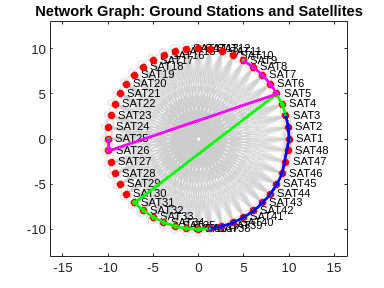

% Number of ground stations and satellites
num_sats = 48;

% Create a graph object
G = graph();

% Load the Satellite Contact Matrix
Sat_to_Sat = sat_to_sat_contact_3d_matrix(:,:,time_index);

% Add Satellites as nodes
for i = 1:num_sats
    G = addnode(G, sprintf('SAT%d', i));
end


% Add edges between Satellites
for i = 1:num_sats
    for j = 1:num_sats
        if Sat_to_Sat(i, j) == 1
            G = addedge(G, sprintf('SAT%d', i), sprintf('SAT%d', j));
        end
    end
end

pi = 3.1415026535;
satellite_radius = 10;

% Satellite positions
satellite_angles = linspace(0, 2*pi, num_sats+1);
satellite_angles = satellite_angles(1:end-1);
satellite_x = satellite_radius * cos(satellite_angles);
satellite_y = satellite_radius * sin(satellite_angles);

% Plot the network graph
figure;
plot(G, 'XData', satellite_x, 'YData', satellite_y, 'NodeColor', [0.6 0.6 0.6], 'EdgeColor', [0.8 0.8 0.8], 'LineWidth', 1);
hold on;

% Plot the ground stations in blue and the satellites in red
plot(satellite_x, satellite_y, 'ro', 'MarkerSize', 5, 'MarkerFaceColor', 'r');


% Load the Dataset Handovering Sequence
Data_Transmission_Sequence_1 = zeros(length(simulation_result_1(:,2)),2);
Data_Transmission_Sequence_2 = zeros(length(simulation_result_2(:,2)),2);
Data_Transmission_Sequence_3 = zeros(length(simulation_result_3(:,2)),2);

for ii = 1:length(simulation_result_1(:,2))
Data_Transmission_Sequence_1(ii,:) =[satellite_x(simulation_result_1(ii,2)), satellite_y(simulation_result_1(ii,2))];
end

% Plot the graph of data transmission sequence
plot(Data_Transmission_Sequence_1(:,1),Data_Transmission_Sequence_1(:,2),'go', 'MarkerSize', 3, 'MarkerFaceColor', 'G')
plot(Data_Transmission_Sequence_1(:,1),Data_Transmission_Sequence_1(:,2),'g','LineWidth',2);


for ii = 1:length(simulation_result_2(:,2))
Data_Transmission_Sequence_2(ii,:) =[satellite_x(simulation_result_2(ii,2)), satellite_y(simulation_result_2(ii,2))];
end

% Plot the graph of data transmission sequence
plot(Data_Transmission_Sequence_2(:,1),Data_Transmission_Sequence_2(:,2),'bo', 'MarkerSize', 3, 'MarkerFaceColor', 'G')
plot(Data_Transmission_Sequence_2(:,1),Data_Transmission_Sequence_2(:,2),'b','LineWidth',2);


for ii = 1:length(simulation_result_3(:,2))
Data_Transmission_Sequence_3(ii,:) =[satellite_x(simulation_result_3(ii,2)), satellite_y(simulation_result_3(ii,2))];
end

% Plot the graph of data transmission sequence
plot(Data_Transmission_Sequence_3(:,1),Data_Transmission_Sequence_3(:,2),'mo', 'MarkerSize', 3, 'MarkerFaceColor', 'G')
plot(Data_Transmission_Sequence_3(:,1),Data_Transmission_Sequence_3(:,2),'m','LineWidth',2);

hold off

% Adjust the axis limits to fit the plot
axis equal;
title('Network Graph: Ground Stations and Satellites');